 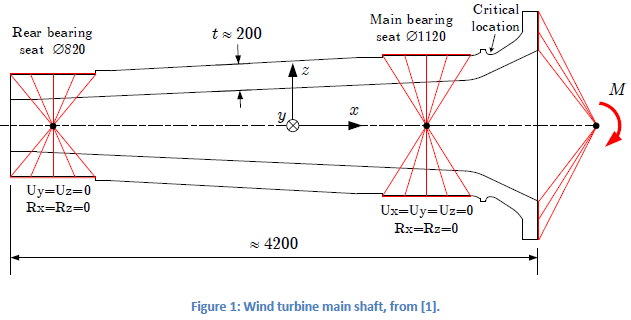

clear all
clf
S_a_k = 206.2;
% n = K_t / K_f
E = 169*1e9;
nu = 0.27;
R_m = 400; %MPa 
R_z = 3.2; %m
% P_s = 97.7 procent
y_Mf = 1.265;

alpha_n = 0.32;
beta_n = 0.77;
%point 147431 (a)	204,2	2.521,83374023	-0,00000000	568,65960693
%point 13268 (b)	154,4	2.521,38549805	-0,00000000	563,48132324
% x_1 = 568.65960693;
% x_2 = 563.48132324;
% S_1 = 204.2;
% S_2 = 154.4;
% 23	201,3	2524.34423828	-0,00000000	568.56097412
% 13267	163,6	2527.02172852	-0,00000000	563.32415771

x_1 = 2524.34423828;
x_2 = 2527.02172852;
z_1 = 568.56097412;
z_2 = 563.32415771;
S_max = 206.2;
S_1 = 201,3;

S_1 = 201

S_2 = 163,6;

S_2 = 163

S_max = S_a_k

S_max = 206.2000

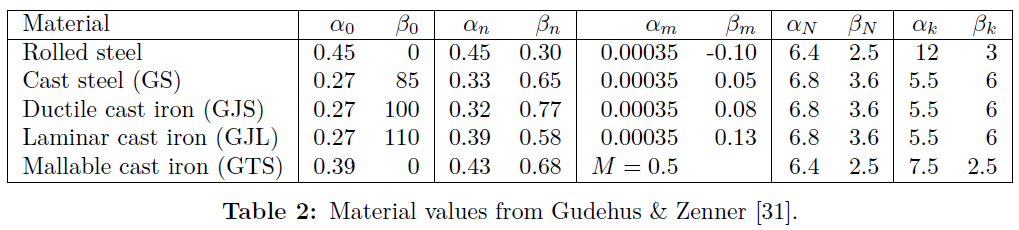


$$\chi^* = \left| \frac{\Delta\sigma}{\sigma_{k,max} \Delta x} \right|$$


dl = sqrt((x_1 - x_2)^2 + (z_1 - z_2)^2)

dl = 5.8816

dS = S_1 - S_2

dS = 38

S_1/S_max- S_2/S_max

ans = 0.1843

X_grad = (S_1/S_max- S_2/S_max)/dl

X_grad = 0.0313

n = 1 + alpha_n * X_grad^beta_n

n = 1.0222

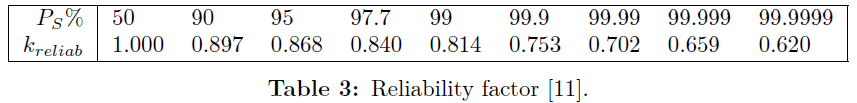

k_chill = 1.5;
k_reliab = 0.840;
k_surf = 1 - 0.22*log10(R_z)^0.64 * log10(R_m) + 0.45*log10(R_z)^0.53

k_surf = 0.9436

k_mean = 1;
% k_load = %1.0 for bending %0.85 for axial %0.59 for torsion % is
% sometimes used intead of mean stress

k_env = 1;

t_ref = 147%25; %

t_ref = 147

t = 2524%147; % vægtykkelse i kritisk område

t = 2524



alpha_t = 0.15;
t_ref = 147; %
t = 2524; % vægtykkelse i kritisk område

k_size = (t_ref/t)^alpha_t

k_size = 0.6528


t_ref = 25; %
t = 147; % vægtykkelse i kritisk område

k_size = (t_ref/t)^alpha_t

k_size = 0.7666


N_D = 1e6;
N_end = 1e9;
m1 = 5;
m2 = 2*m1 - 1

m2 = 9

alpha_0 = 0.27;
beta_0 = 100;

S_RD_mat = alpha_0 * R_m + beta_0

S_RD_mat = 208


S_RDk = k_size * k_surf * k_mean * k_env  * n * k_chill * S_RD_mat%  S_RD_mat / y_Mf * k_reliab

S_RDk = 230.7160


C1 = S_RDk^m1 * N_D

C1 = 6.5372e+17

C2 = S_RDk^m2 * N_D

C2 = 1.8523e+27

Vi finder punkter til plotet

N_start = 1e4

N_start = 10000

S_start =   (C1 /N_start)^(1/m1) 

S_start = 579.5325



% N_exp = 2.3e6;
S_end = (C2 / N_end)^(1/m2) %finder et punkt for S_1 med vores maximale lokal spænding

S_end = 107.0889

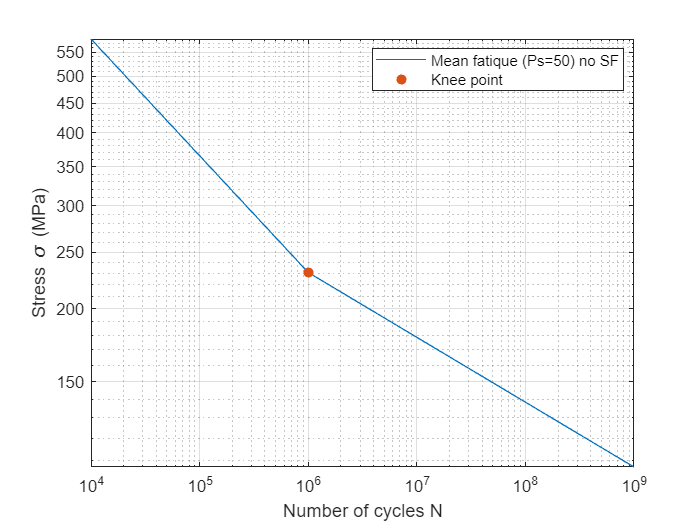



S_1s = [S_start,S_RDk, S_end];
N_1s = [N_start,N_D, N_end];


loglog(N_1s, S_1s, DisplayName="Mean fatique (Ps=50) no SF")
hold on
scatter(N_D,S_RDk, "filled", DisplayName="Knee point")
xlabel('Number of cycles N')
ylabel('Stress \sigma (MPa)')
legend('location', 'best')
grid("on")

hold off

P=97,7 uden sikkerhed

S_RDk_no_safe_97 = k_size * k_surf * k_mean * k_env * k_reliab* k_chill  * n  * S_RD_mat%/ y_Mf

S_RDk_no_safe_97 = 193.8015


C1_no_safe_97 = S_RDk_no_safe_97^m1 * N_D;
C2_no_safe_97 = S_RDk_no_safe_97^m2 * N_D;

S_start_no_safe_97 = (C1_no_safe_97 / N_start)^(1/m1)

S_start_no_safe_97 = 486.8073

S_end_no_safe_97 = (C2_no_safe_97 / N_end)^(1/m2) %finder et punkt for S_1 med vores maximale lokal spænding

S_end_no_safe_97 = 89.9547


S_1s_no_safe_97 = [S_start_no_safe_97,S_RDk_no_safe_97, S_end_no_safe_97];
N_1s_no_safe_97 = [N_start,N_D, N_end];


P = 97,7 Med sikkerhed

S_RDk_safe_97 = k_size * k_surf * k_mean * k_env * k_reliab* k_chill  * n  * S_RD_mat / y_Mf

S_RDk_safe_97 = 153.2027


C1_safe_97 = S_RDk_safe_97^m1 * N_D;
C2_safe_97 = S_RDk_safe_97^m2 * N_D;

S_start_safe_97 = (C1_safe_97 / N_start)^(1/m1)

S_start_safe_97 = 384.8279

S_end_safe_97 = (C2_safe_97 / N_end)^(1/m2) %finder et punkt for S_1 med vores maximale lokal spænding

S_end_safe_97 = 71.1104


S_1s_safe_97 = [S_start_safe_97,S_RDk_safe_97, S_end_safe_97];
N_1s_safe_97 = [N_start,N_D, N_end];


Plot laves

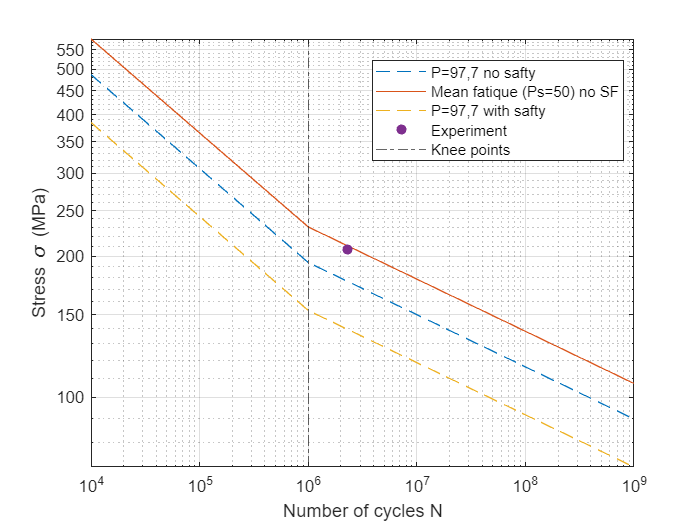

S_last = S_max; %S_a = 81.9;
N_last = 2.3e6;


loglog(N_1s_no_safe_97, S_1s_no_safe_97, '--', DisplayName='P=97,7 no safty')
hold on
loglog(N_1s, S_1s, DisplayName="Mean fatique (Ps=50) no SF")
loglog(N_1s_safe_97, S_1s_safe_97, '--', DisplayName='P=97,7 with safty')
xline(N_D,'-.', DisplayName='Knee points')
scatter(N_last, S_last, 'filled', DisplayName='Experiment')

xlabel('Number of cycles N')
ylabel('Stress \sigma (MPa)')
% ylim([S_exp-10,S_1+10])
% xlim([0,N_exp+1e5])
legend('location', 'best')
grid("on")

hold off

??